clear;
clc;
map=dlmread("Assignment#2/OccupancyMapNew.dat");
[laser, odometry, end_time,robot] =extract("Assignment#2/robotdata1.log");
% [x_laser,y_laser]=[x_robot+25*cos(tetha_robot),y_robot+25*sin(theta_robot)];
% need

a way to represent bel(xt) with particles

a map

a sensor model

a motion model

a procedure for updating bel(xt)

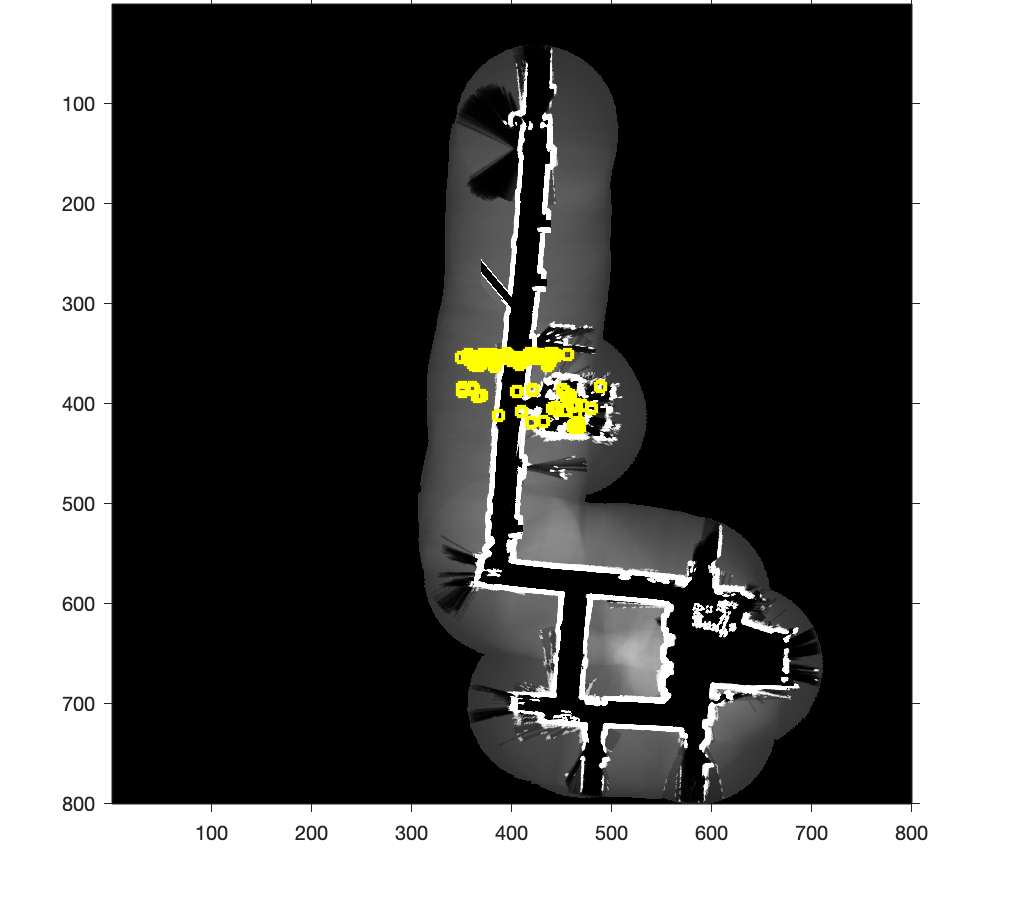

imshow(map)
N=100;
T=1;
C=0;
x=randi([0 800]);
y=randi([0 800]);



probab_occupied=map(x,y);
hold on
axis on
% plot(x,y,'ys','LineWidth',2) 
for i = 1:2
    robot_calliberated(:,i)=robot(:,i)/10;
end
% plot a point if the probability of the grid being occupied is less than 35%
% initial position (350:500,350:425)
while C<100
    x=randi([350 500]);
    y=randi([350 425]);
   
   if and(map(x,y)<0.35,map(x,y)>0)
         plot(x,y,'ys','LineWidth',2) 
         C=C+1;
   end  
              
end

function [laser, odometry, end_time ,robot] = extract(file)
    fid = fopen(file);
    tline = fgetl(fid);

    odometry_line = 1;
    laser_line = 1;
    coordinate=1;
    end_time = 0;

    while ischar(tline)
        ans = strsplit(tline);

        if (strcmp(ans(1),'L'))
            laser(laser_line,1) = str2double(ans(2)); % x_robot
            robot(coordinate,1)=str2double(ans(2));
            
            laser(laser_line,2) = str2double(ans(3)); % y_robot
            robot(coordinate,2)=str2double(ans(3));
            
            laser(laser_line,3) = str2double(ans(4)); % theta_robot
            robot(coordinate,3)=str2double(ans(4));
            
            laser(laser_line,4) = str2double(ans(5)); % x_laser
            laser(laser_line,5) = str2double(ans(6)); % y_laser
            
            laser(laser_line,6) = str2double(ans(7)); % theta_laser
            
            
            for i = 8:187
                laser(laser_line,i-1) = str2double(ans(i)); % scanner measurement
            end

            laser(laser_line, 187) = str2double(ans(188)); % time_stamp
            robot(coordinate,4)=str2double(ans(188));

            laser_line= laser_line + 1;
            coordinate=coordinate+1;
            end_time = str2double(ans(188));
        else
            odometry(odometry_line,1) = str2double(ans(2)); % x_robot
             robot(coordinate,1)=str2double(ans(2));
             
            odometry(odometry_line,2) = str2double(ans(3)); % y_robot
            robot(coordinate,2)=str2double(ans(3));
            
            odometry(odometry_line,3) = str2double(ans(4)); % theta_robot
            robot(coordinate,3)=str2double(ans(4));
            
            odometry(odometry_line,4) = str2double(ans(5)); % time_stamp
            robot(coordinate,4)=str2double(ans(5));
            
            odometry_line= odometry_line+ 1;
            coordinate=coordinate+1;
            end_time = str2double(ans(5));
        end

        tline = fgetl(fid);
    end
end